clear; close all; clc;
set(groot, 'defaultLegendInterpreter','latex'); 

## Defining Physical Parameters and Sensor Gains

The following lines of code will define the sensor gains and physical parameters used for the simulation.

Ka     = 5.1793;     % Power Amplifier
N      = 8.1;        % Speed Reduction Factor
Km     = 22.289;     % Motor gain [rad/s/V]
Km_lin = 19.763;     % Linearized motor gain [rad/s/V]
tau_m  = .2740;      % Motor time constant [s]
Kp     = 4.90379;    % Position Feedback Gain
Kt     = .1429;
vmo    = 0.66;       % Voltage to hold pendulum at 90 degrees [V]
g      = 9.81;       % gravitational acceleration [m/s/s]

#### Defining physical parameters of the pendulum

L = 0;      % Pendulum rod length [in]
m = 0; % Bob mass [kg]
physParam = [m, L, g, vmo, N];

The next line will define the intial condition of the pendulum

th_init = deg2rad(0);
Vin = 1.53;
simout = sim('motomatic_pend_OL.slx',2);

speed = readtable("Step1Orig.csv");

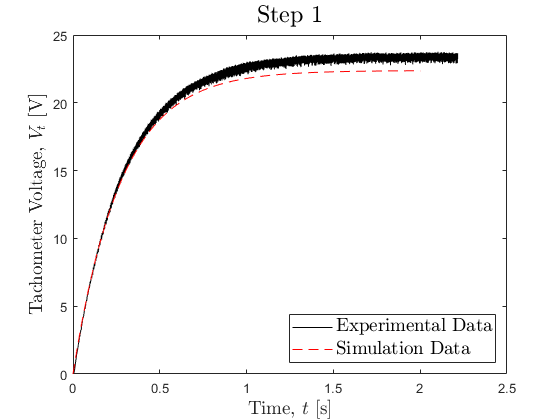

figure;
plot(speed.Time_s_,speed.Math1_V_,'k');
hold on
plot(simout.tout, simout.vt,'r--')
hold off
xlabel('Time, $t$ [s]','Interpreter','Latex','FontSize',14); 
ylabel('Tachometer Voltage, $V_t$ [V]','Interpreter','Latex','FontSize',14);
xlim([0 2.5]); ylim([0 25]);
title('Step 1','Interpreter','Latex','FontSize',18)
legend('Experimental Data','Simulation Data','location','southeast','fontsize',14);